# EPR UK 1000

clear; close all; clc;

## Dane:

ThermalPower = 4500e6;          %   [W]     moc cieplna reaktora
ActiveHeight = 4200/1000;       %   [m]     wysokość aktywnej części rdzenia
Pressure = 155;                 %   [bar]   ciśnienie na wlocie do rdzenia
NAssembly = 241;                %   [-]     liczba kaset paliwowych
NRods = 265;                    %   [-]     liczba prętów paliwowych w kasecie
NSpacer = 10;                   %   [-]     liczba siatek dystansujących
TempInput = 295.6;              %   [°C]    temperatura wlotowa
WaterFlux = 75643000/3600;      %   [kg/s]  strumień masy wody chłodzącej
AssemblyPitch = 214/1000;       %   [m]     skok siatki kaset
RodDiameter = 9.5/1000;         %   [m]     średnica pręta paliwowego
RodPitch = 12.6/1000;           %   [m]     skok siatki prętów w kasecie
UraniumMass = 527.5 * NAssembly;%   [kg]    masa materiału rozszczepialnego w rdzeniu
ExLength = 50/1000;             %   [m]     długość ekstrapolacji
CladThickness = 0.57/1000;      %   [m]     grubość koszulki
GapThickness = 0.17/1000;       %   [m]     grubość przerwy między paliwem, a koszulką
PelletDiameter = 8.19/1000;     %   [m]     średnica pastylki paliwowej
g = 9.81;                       %   [m/s2]  przyspieszenie ziemskie
Pxy = 1.61;                     %   [-]     Wsp. promieniowy nierównomierności rozkładu

Te chyba nie są potrzebne

NeutronVelocity = 2200;         %   [m/s]  prędkość neutronów termicznych
SigmaU235 = 505e-24 * 1e-4;     %   [m]    efektywny mikroskopowy przekrój czynny na rozszczepienie dla neutronów termicznych dla U235
N_U235 = 1.3457e+20 * 1e6;      %   [1/m3] gęstość liczbowa/atomowa materiału rozszczepialnego
w_tot = 200 * 1e6 * 1.602e-19;  %   [J]    energia na jedno roszczepienie

## 0. Przyrost temperatury w rdzeniu

Cp = 1000 * XSteam('Cp_pT', Pressure, TempInput);
DeltaTemp = ThermalPower / (Cp * WaterFlux);
TempOutput = TempInput + DeltaTemp;
TempAvg = (TempInput + TempOutput) / 2;

Iteracja 2:

Cp = 1000 * XSteam('Cp_pT', Pressure, TempAvg);
DeltaTemp = ThermalPower / (Cp * WaterFlux)

DeltaTemp = 35.9998

TempOutput = TempInput + DeltaTemp;
TempAvg = (TempInput + TempOutput) / 2;

Iteracja 3:

Cp = 1000 * XSteam('Cp_pT', Pressure, TempAvg);
DeltaTemp = ThermalPower / (Cp * WaterFlux)

DeltaTemp = 36.4772

TempOutput = TempInput + DeltaTemp;
TempAvg = (TempInput + TempOutput) / 2;

## 1. Liniowa gęstość mocy

Liczba reakcji:

w_f = 0.95 * w_tot;                             %   [J]    odzyskiwalna energia
NReactions = ThermalPower / w_f;                %   [1/s]  liczba reakcji w rdzeniu

Objętość rdzenia:

AssemblyArea = AssemblyPitch^2;                         %   [m2]    powierzchnia przekroju poprzecznego jednej kasety
CoreVolume = AssemblyArea * ActiveHeight * NAssembly;   %   [m3]    objętość rdzenia

Szybkość reakcji:

Rf = NReactions * CoreVolume;                   %   [1/m3/s]    średnia szybkość reakcji w rdzeniu
Phi = Rf / (SigmaU235 * N_U235);                %   [1/m2/s]    średni strumień neutronów

Gęstość mocy rdzenia (objętościowa):

PowerDensityVol = ThermalPower / CoreVolume;    %   [W/m3]  średnia objętościowa gęstość mocy

Gęstość mocy rdzenia (właściwa):

PowerDensitySpec = ThermalPower / UraniumMass;  %   [W/kgU]     średnia właściwa gęstość mocy

Moc kasety:

AssemblyPower = ThermalPower / NAssembly;       %   [W]     średnia moc kasety

Moc pręta:

RodPower = AssemblyPower / NRods;               %   [W]     średnia moc pręta

Moc liniowa:

LengthTotal = ActiveHeight * NRods * NAssembly; %   [m]     całkowita długość prętów
AvgLinHeatRate = ThermalPower / LengthTotal        %   [W/m]   średnia moc liniowa

AvgLinHeatRate = 1.6776e+04

## 1. Rozkład mocy wzdłuż kanału

ExHeight = ActiveHeight + 2 * ExLength;                                                                 %   [m]     wysokość rdzenia + 2 długości ekstrapolacji
AvgChannelAvgPower = ThermalPower / (NAssembly * NRods);                                                      %   [W]     średnia moc kanału
HotChannelAvgPower = AvgChannelAvgPower * Pxy;
AvgChannelPowerMax = pi * AvgChannelAvgPower / (ExHeight * 2 * sin((pi * ActiveHeight) / (2 * ExHeight)));    %   [W/m]     maksymalna moc dla średniego kanału
HotChannelPowerMax = AvgChannelPowerMax * Pxy;                                                          %   [W/m]     maksymalna moc dla gorącego kanału

rozkład mocy w kanałach:

z = linspace(-ActiveHeight/2, ActiveHeight/2, 100);
AvgChannelPower =  AvgChannelPowerMax * cos(pi * z / ExHeight);     %   rozkład mocy liniowej średniego kanału
HotChannelPower =  HotChannelPowerMax * cos(pi * z / ExHeight);     %   rozkład mocy liniowej gorącego kanału

Wykres:

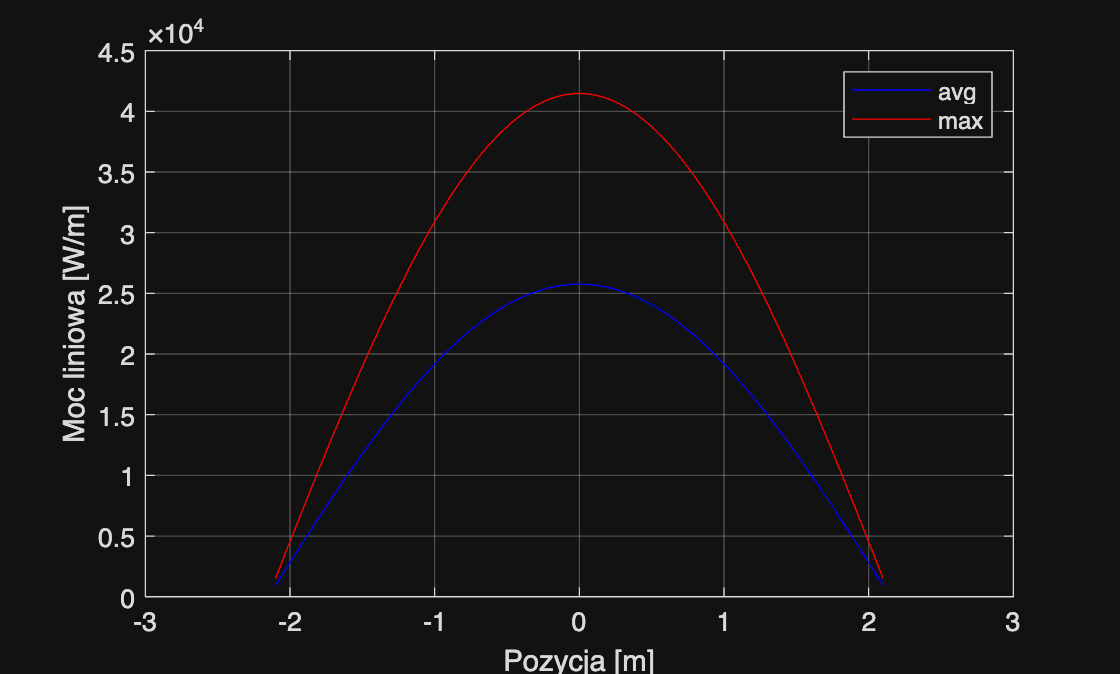

figure(1); grid on; box on; hold on;
ylabel("Moc liniowa [W/m]")
xlabel("Pozycja [m]")
plot(z, AvgChannelPower, '-b')
plot(z, HotChannelPower, '-r')
legend('avg', 'max')
hold off;

Strumienie ciepła:

AvgChannelHeatFlux = AvgChannelPower .* cos(pi * z / ExHeight) / (pi * RodDiameter);
HotChannelHeatFlux = HotChannelPower .* cos(pi * z / ExHeight) / (pi * RodDiameter);

Wykres:

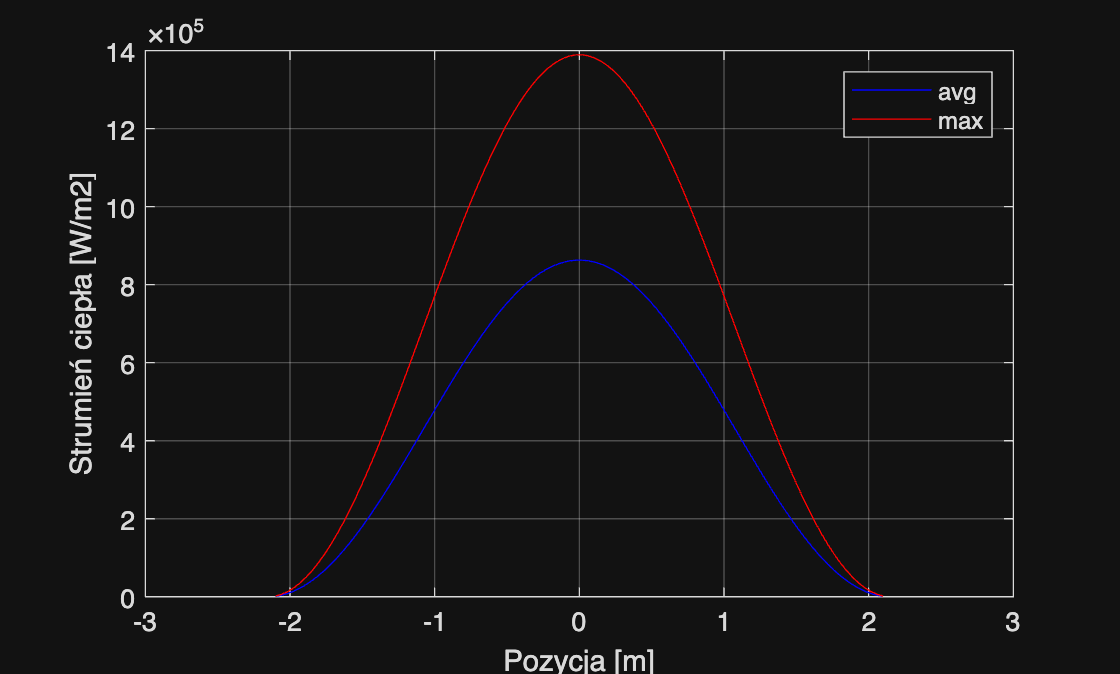

figure; grid on; box on; hold on;
ylabel("Strumień ciepła [W/m2]")
xlabel("Pozycja [m]")
plot(z, AvgChannelHeatFlux, "b-")
plot(z, HotChannelHeatFlux, "r-")
legend('avg', 'max')
hold off;

## 2. Rozkład temperatury w kanale

WaterFluxChannel = WaterFlux / (NAssembly * NRods);                     %   [kg/s]      strumień masy wody w kanale
TempAvgChannel = TempInput + (AvgChannelPowerMax/(WaterFluxChannel * Cp)) * (ExHeight / pi) * (sin(pi * z / ExHeight) + sin(pi * ActiveHeight / (2 * ExHeight)));     %   rozkład temperatury w kanale średnim
TempHotChannel = TempInput + (HotChannelPowerMax/(WaterFluxChannel * Cp)) * (ExHeight / pi) * (sin(pi * z / ExHeight) + sin(pi * ActiveHeight / (2 * ExHeight)));     %   rozkład temperatury w kanale średnim

Wykres:

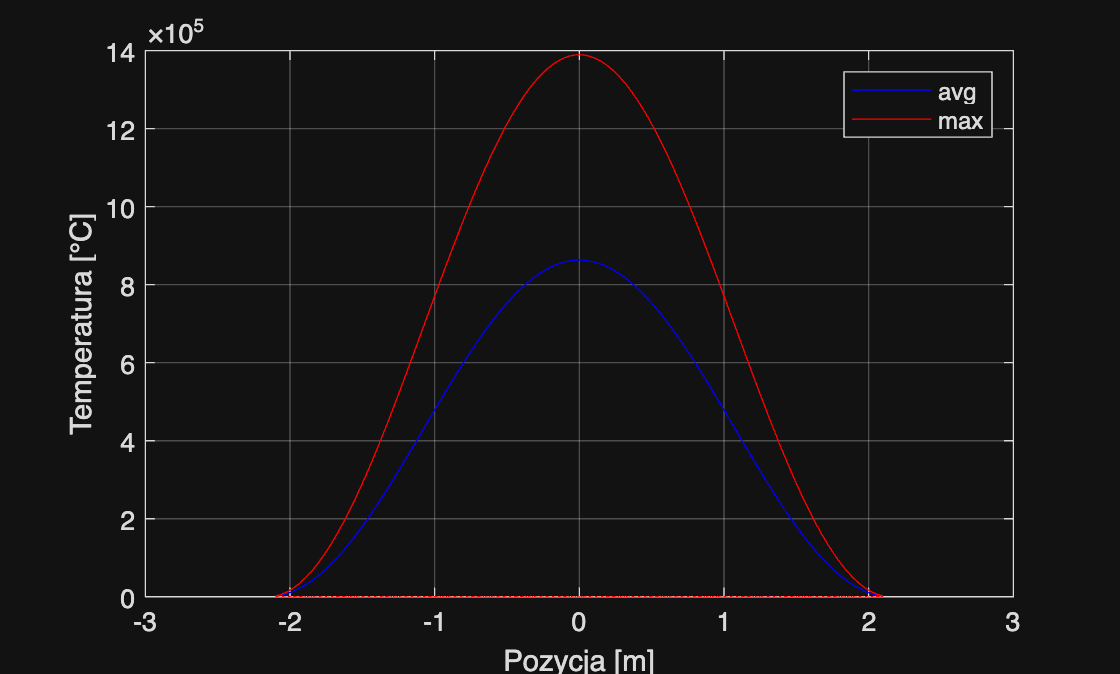

figure(2); grid on; box on; hold on;
xlabel("Pozycja [m]")
ylabel("Temperatura [°C]")
plot(z, TempAvgChannel, "b-")
plot(z, TempHotChannel, "r-")
legend('avg', 'max')
hold off;

## 3. Rozkład temperatury zewnętrznej koszulki

Średnica hydrauliczna:

FlowArea = RodPitch^2 - (pi / 4) * RodDiameter^2;
WetPerimeter = pi * RodDiameter;
HydraulicDiameter = 4 * FlowArea / WetPerimeter

HydraulicDiameter = 0.0118

G = WaterFluxChannel / FlowArea;

Liczba Reynoldsa i liczba Prandtla:

Mu = XSteam('my_pT', Pressure, TempInput);
Re = G * HydraulicDiameter / Mu

Re = 4.8869e+05

k = XSteam('tc_pt', Pressure, TempInput);
Pr = Cp * Mu / k

Pr = 0.9334

Liczba Nusselta:

NuDB = 0.023 * (Re^(0.8)) * (Pr^0.4)

NuDB = 796.1160

B = (4 / pi) * (RodPitch / RodDiameter)^2 - 1;
NuMarkoczy = (1 + 0.91 * (Re^(-0.1)) * (Pr^0.4) * (1 - 2 * exp(-B))) * NuDB

NuMarkoczy = 876.1949

Współczynnik przejmowania ciepła:

hDB = NuDB * k / HydraulicDiameter;
hMarkoczy = NuMarkoczy * k / HydraulicDiameter;
h = hMarkoczy

h = 4.2225e+04

Przyrost temperatury przepływ - paliwo:

AvgDeltaTempWall = AvgChannelPower ./ (pi * RodDiameter * h);
HotDeltaTempWall = HotChannelPower ./ (pi * RodDiameter * h);

Temperatura powierzchni koszulki:

TempAvgCladOuter = TempAvgChannel + AvgDeltaTempWall;
TempHotCladOuter = TempHotChannel + HotDeltaTempWall;

Wykres:

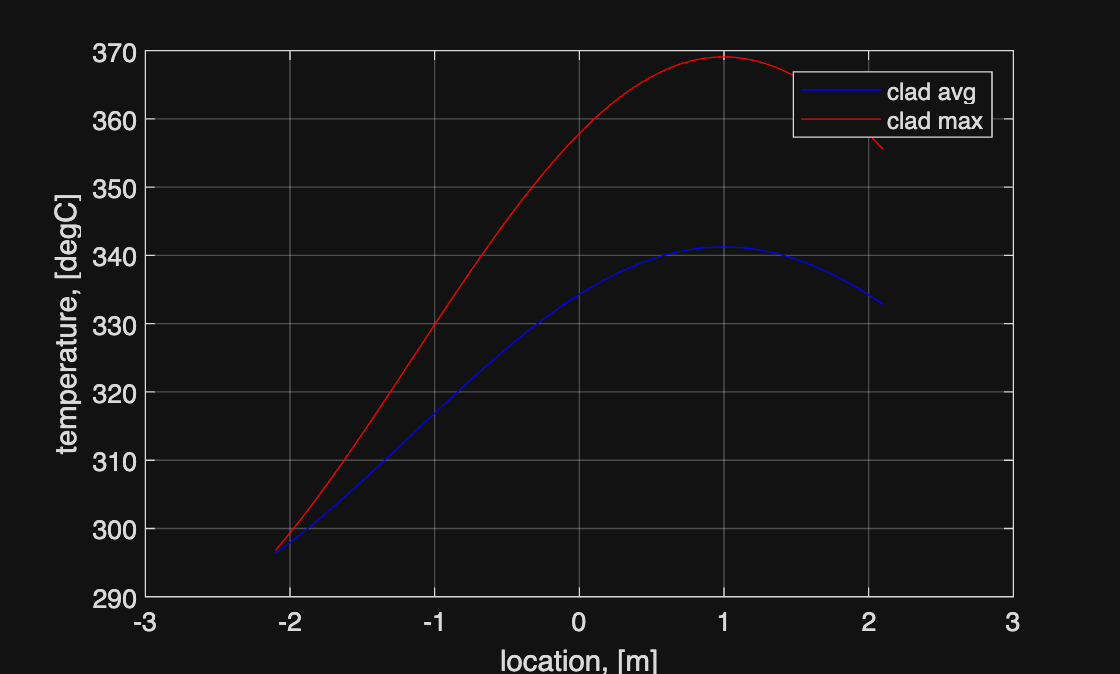

figure(3); grid on; box on; hold on;
plot(z, TempAvgCladOuter, '-b')
plot(z, TempHotCladOuter, '-r')
legend('clad avg', 'clad max')
xlabel('location, [m]')
ylabel('temperature, [degC]')
hold off;

AvgTempAvgCladOuter = mean(TempAvgCladOuter)

AvgTempAvgCladOuter = 327.0244

max(TempAvgCladOuter)

ans = 341.2398

max(TempHotCladOuter)

ans = 369.0801

min(TempAvgCladOuter)

ans = 296.3465

min(TempHotCladOuter)

ans = 296.8018

## 4. Rozkład temperatury wewnętrznej koszulki

Przewodność cieplna koszulki:

kClad = k_ZR(AvgTempAvgCladOuter)

kClad = 12.9570

Przyrosty temperatury:

GapDiameter = RodDiameter - 2 * CladThickness;
AvgDeltaTempCladInner = (AvgChannelPower / (2 * pi * kClad)) * log(GapDiameter/PelletDiameter);
HotDeltaTempCladInner = (HotChannelPower / (2 * pi * kClad)) * log(GapDiameter/PelletDiameter);

Wykres:

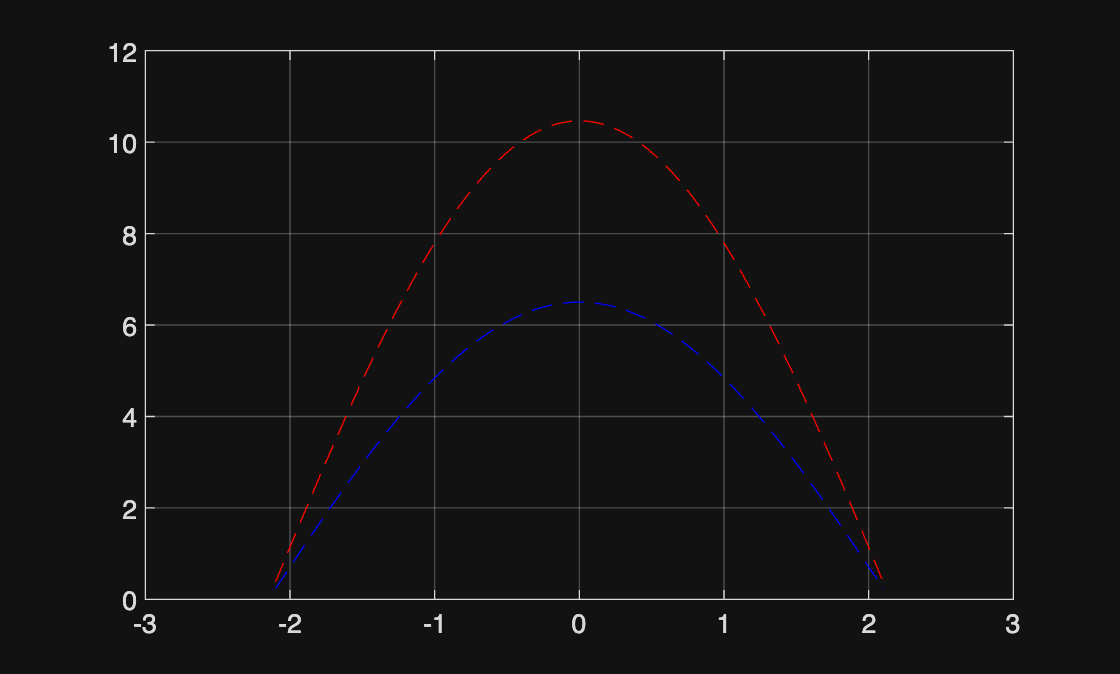

figure(4); grid on; box on; hold on;
plot(z, AvgDeltaTempCladInner, '--b')
plot(z, HotDeltaTempCladInner, '--r')
hold off;

Temperatury:

TempAvgCladInner = TempAvgCladOuter + AvgDeltaTempCladInner;
TempHotCladInner = TempHotCladOuter + HotDeltaTempCladInner;

Wykres:

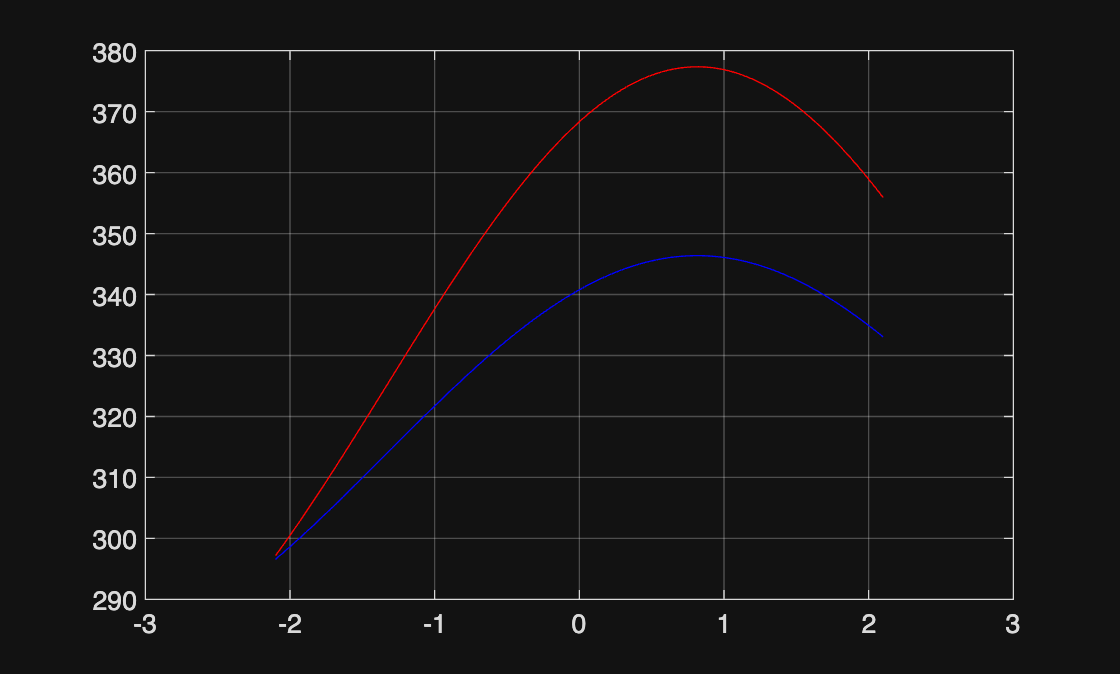

figure(5); grid on; box on; hold on;
plot(z, TempAvgCladInner, '-b')
plot(z, TempHotCladInner, '-r')
hold off;

max(TempAvgCladInner)

ans = 346.3760

max(TempHotCladInner)

ans = 377.3494

min(TempAvgCladInner)

ans = 296.5838

min(TempHotCladInner)

ans = 297.1840

Wykres łączny:

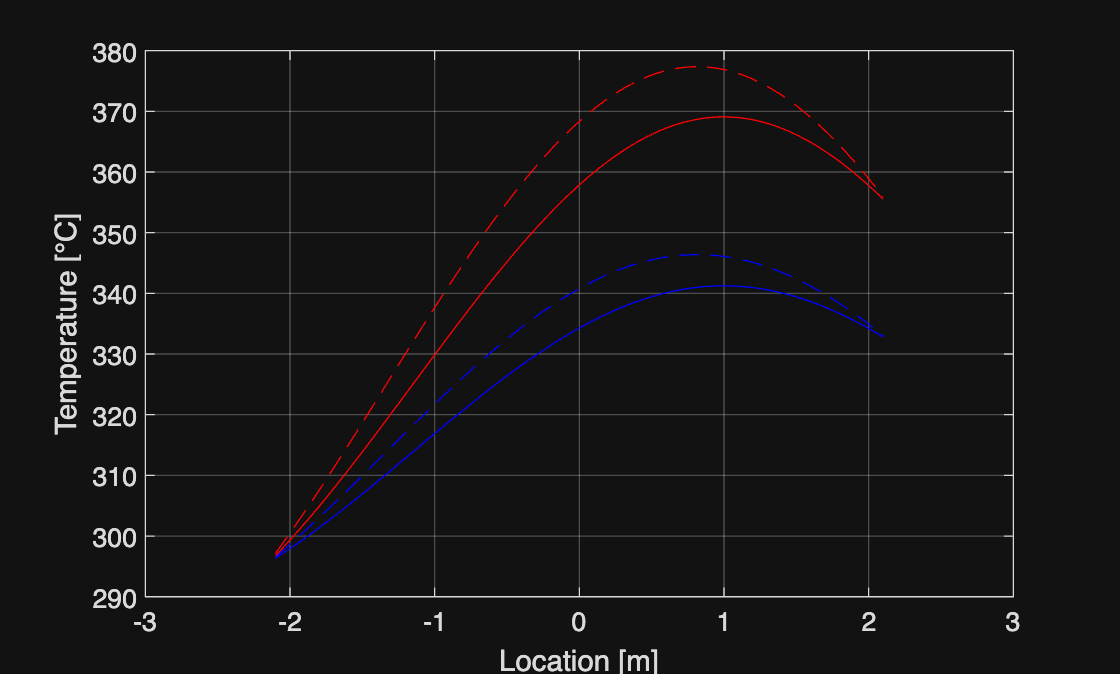

figure (6); grid on; box on; hold on;
plot(z, TempAvgCladInner, '--b')
plot(z, TempHotCladInner, '--r')
plot(z, TempAvgCladOuter, '-b')
plot(z, TempHotCladOuter, '-r')
hold off;
xlabel('Location [m]')
ylabel('Temperature [°C]')

## 5. Rozkład temperatury na powierzchni paliwa

Przyrost temperatury w szczelinie:

hGap = 10000;
AvgDeltaTempGap = AvgChannelPower ./ (PelletDiameter * pi * hGap);
HotDeltaTempGap = HotChannelPower ./ (PelletDiameter * pi * hGap);
TempAvgPelletOuter = TempAvgCladInner + AvgDeltaTempGap;
TempHotPelletOuter = TempHotCladInner + HotDeltaTempGap;

Przyrost temperatury w paliwie:

kPellet = k_UO2(mean(TempAvgPelletOuter));
AvgDeltaTempPellet = AvgChannelPower / (4 * pi * kPellet);
HotDeltaTempPellet = HotChannelPower / (4 * pi * kPellet);
TempAvgPelletInner = TempAvgPelletOuter + AvgDeltaTempPellet;
TempHotPelletInner = TempHotPelletOuter + HotDeltaTempPellet;

Wykres spadku temperatury powierzchni paliwa:

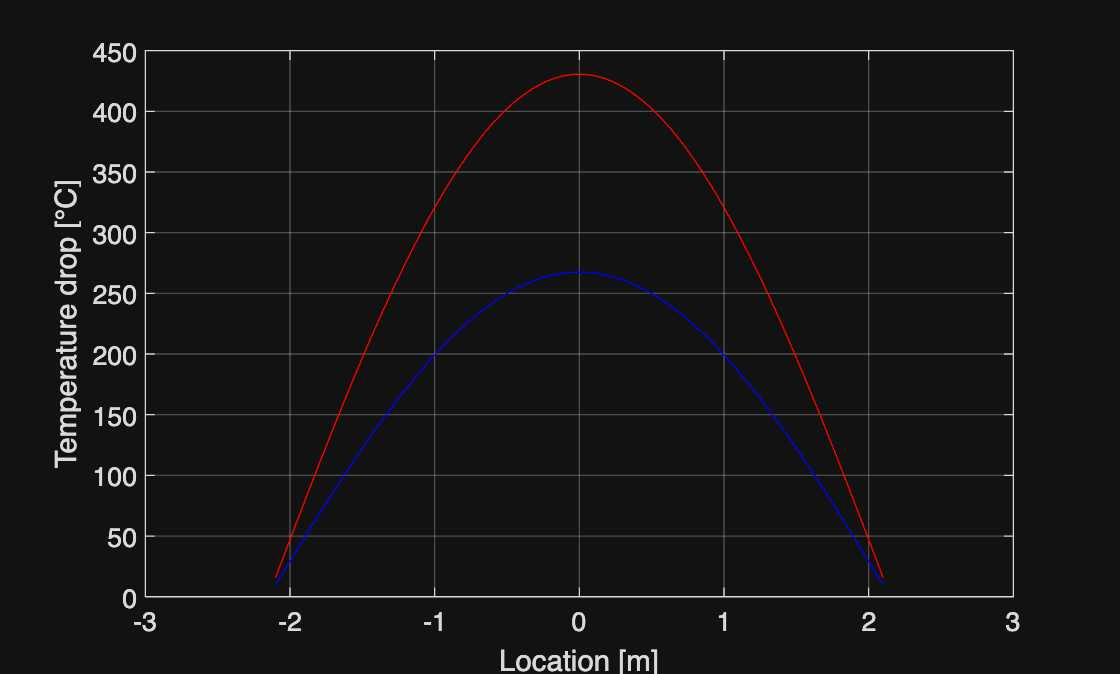

figure (7); grid on; box on; hold on;
plot(z, AvgDeltaTempPellet, '-b')
plot(z, HotDeltaTempPellet, '-r')
hold off;
xlabel('Location [m]')
ylabel('Temperature drop [°C]')

Wartości maksymalne:

max(AvgDeltaTempPellet)

ans = 267.4052

max(HotDeltaTempPellet)

ans = 430.5224

max(TempAvgPelletInner)

ans = 708.7416

max(TempHotPelletInner)

ans = 960.7580

Wykres temperatur w paliwie:

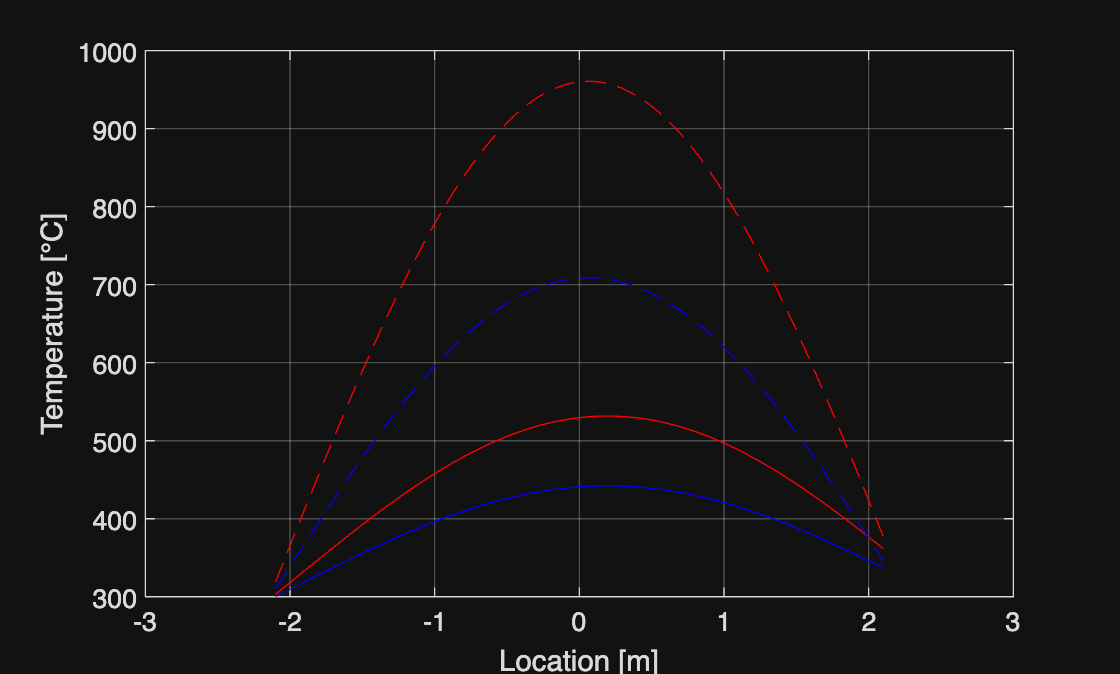

figure (8); grid on; box on; hold on;
plot(z, TempAvgPelletOuter, '-b')
plot(z, TempHotPelletOuter, '-r')
plot(z, TempAvgPelletInner, '--b')
plot(z, TempHotPelletInner, '--r')
hold off;
xlabel('Location [m]')
ylabel('Temperature [°C]')

Wykres wszystkich temperatur w kanale średnim:

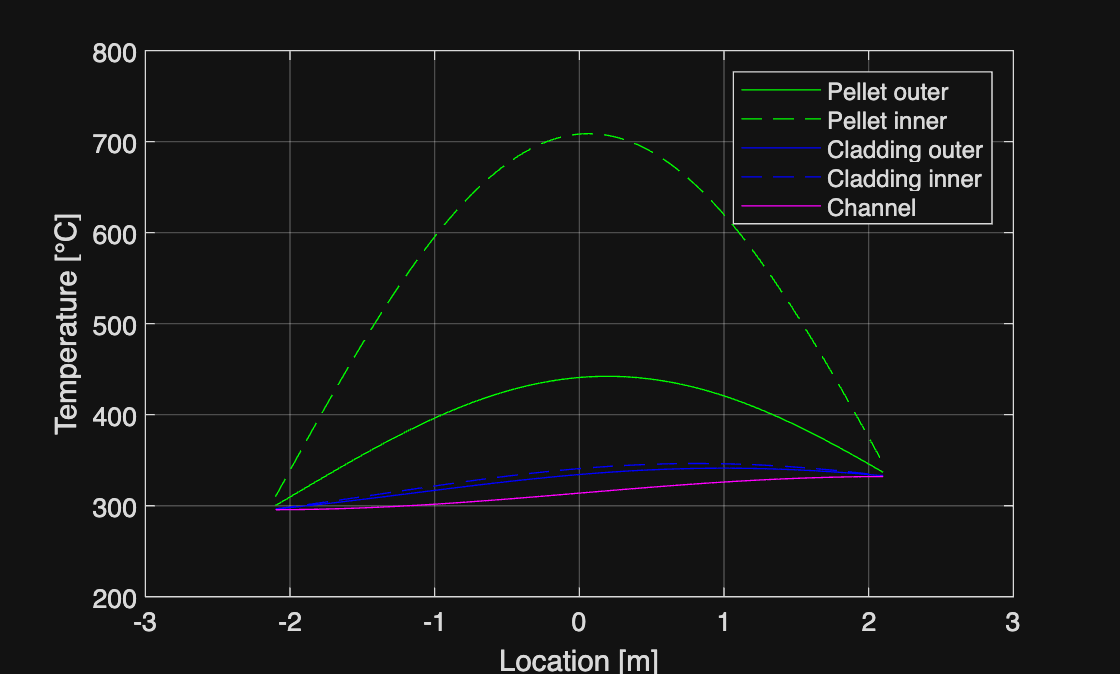

clc; 
figure (9); grid on; box on; hold on;
plot(z, TempAvgPelletOuter, '-g')
plot(z, TempAvgPelletInner, '--g')
plot(z, TempAvgCladOuter, '-b')
plot(z, TempAvgCladInner, '--b')
plot(z, TempAvgChannel, '-m')
hold off;
xlabel('Location [m]')
ylabel('Temperature [°C]')
legend('Pellet outer', 'Pellet inner', 'Cladding outer', 'Cladding inner', 'Channel')

Wykres wszystkich temperatur w kanale gorącym:

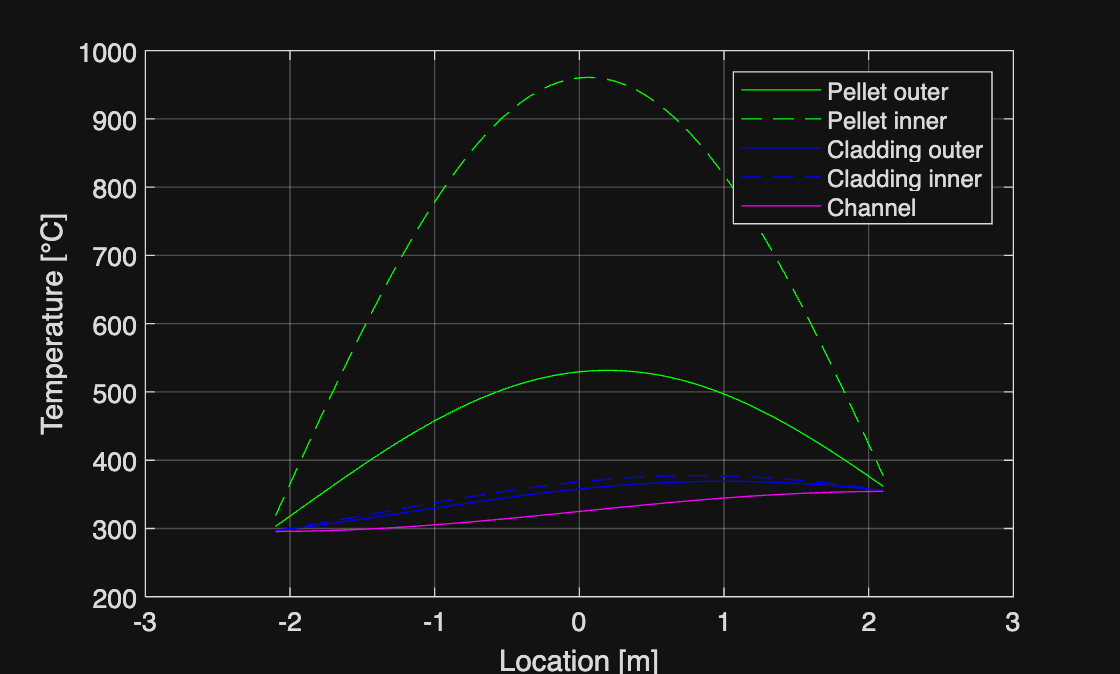

clc;
figure (10); grid on; box on; hold on;
plot(z, TempHotPelletOuter, '-g')
plot(z, TempHotPelletInner, '--g')
plot(z, TempHotCladOuter, '-b')
plot(z, TempHotCladInner, '--b')
plot(z, TempHotChannel, 'm-')
hold off;
xlabel('Location [m]')
ylabel('Temperature [°C]')
legend('Pellet outer', 'Pellet inner', 'Cladding outer', 'Cladding inner', 'Channel')

## 6. Straty ciśnienia

Od tarcia:

kD = 1e-5;
prawa = -1.8 * log10((kD / 3.7)^(1.11) + (6.9 / Re));
lambda = (1 / prawa)^2;
Cf = lambda / 4;
RhoIn = XSteam('rho_pT', Pressure, TempInput);
RhoOut = XSteam('rho_pT', Pressure, TempOutput);
Rho = XSteam('rho_pT', Pressure, TempAvg);
RhoAvg = (RhoIn + RhoOut) / 2;
DeltaPressureFriction = (4 * Cf / HydraulicDiameter) * (WaterFluxChannel^2 / (2 * RhoAvg * FlowArea^2)) * ActiveHeight

DeltaPressureFriction = 4.7904e+04

Od grawitacji:

DeltaPressureGravity = g * ActiveHeight * RhoAvg

DeltaPressureGravity = 2.8435e+04

Od przyspieszenia:

DeltaPressureAcceleration = (((WaterFluxChannel / FlowArea)^2) * (1/RhoOut - 1/RhoIn))

DeltaPressureAcceleration = 2.6762e+03

Straty lokalne - siatki dystansujące:

Eta = 1.95 * Re^(-0.08);
DeltaPressureGrid = Eta * (G^2) / (2 * RhoAvg);
DeltaPressureGridTotal = NSpacer * DeltaPressureGrid

DeltaPressureGridTotal = 6.9439e+04

Straty lokalne - wlot, wylot:

EtaIn = 0.5;
EtaOut = 1.0;
DeltaPressureIn = EtaIn * (G^2) / (2 * RhoAvg)

DeltaPressureIn = 5.0776e+03

DeltaPressureOut = EtaOut * (G^2) / (2 * RhoAvg)

DeltaPressureOut = 1.0155e+04

Całkowita:

DeltaPressureCore = DeltaPressureFriction + DeltaPressureGravity + DeltaPressureAcceleration + DeltaPressureGridTotal + DeltaPressureIn + DeltaPressureOut

DeltaPressureCore = 1.6369e+05

Ciśnienie na wylocie z rdzenia:

PressureInput = Pressure;
PressureOutput = PressureInput - DeltaPressureCore / 1e5

PressureOutput = 153.3631

## 7. Wrzenie pęcherzykowe

HotChannelHeatFluxMax = HotChannelPowerMax / (2 * pi * RodDiameter);
TestPower = trapz(z, HotChannelPower);
RD = 100 * (TestPower - HotChannelAvgPower) / HotChannelAvgPower;

Entalpia:

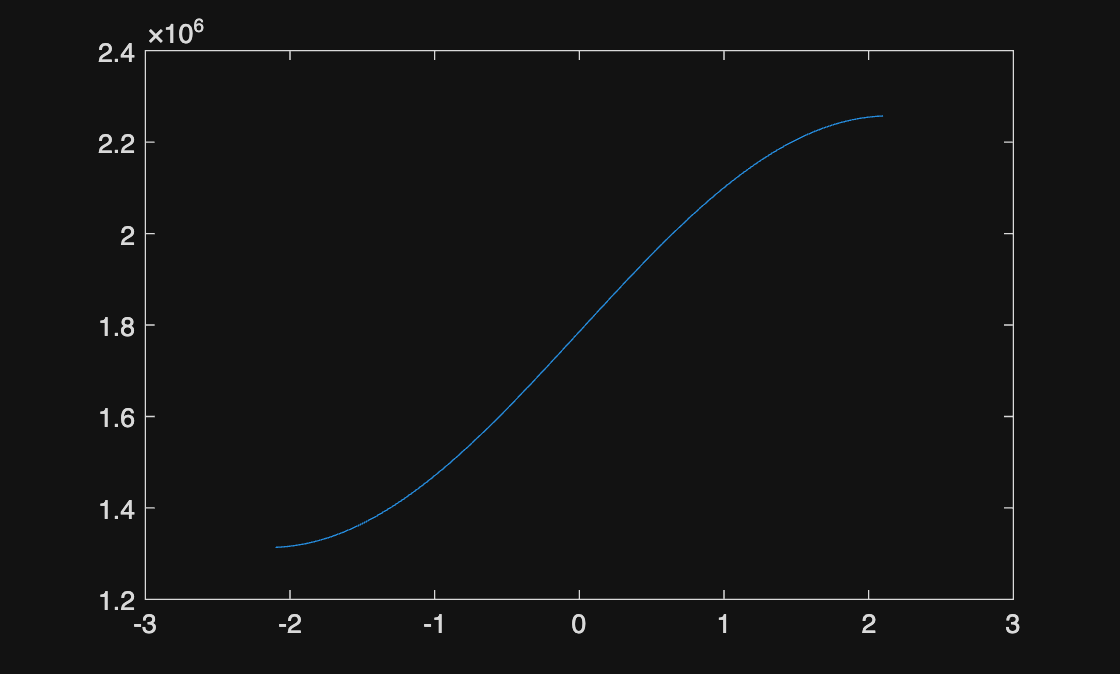

EnthalpyInput = XSteam('h_pT', Pressure, TempInput) * 1000;
ChannelEnthalpy = EnthalpyInput + (HotChannelAvgPower ./ (WaterFluxChannel)) .* (ExHeight ./ pi) .* (sin(pi .* z ./ ExHeight) + sin(pi * ActiveHeight / (2 * ExHeight)));
plot(z, ChannelEnthalpy)

Stopień suchości:

SatEnthalpyG = XSteam('hV_p', Pressure) * 1000;
SatEnthalpyF = XSteam('hL_p', Pressure) * 1000;
xE = (ChannelEnthalpy - SatEnthalpyF) ./ (SatEnthalpyG - SatEnthalpyF);
%plot(z, xE)

CHF:

G   % 750 - 5000

G = 3.7439e+03

Pressure    % 29.4 - 196

Pressure = 155

HydraulicDiameter*1000  % 2 - 45

ans = 11.7778

CrHeatFlux = chf_LevitanLantsman(G, Pressure, xE, HydraulicDiameter) .* 1e6;
max(CrHeatFlux)

ans = 5.5923e+06

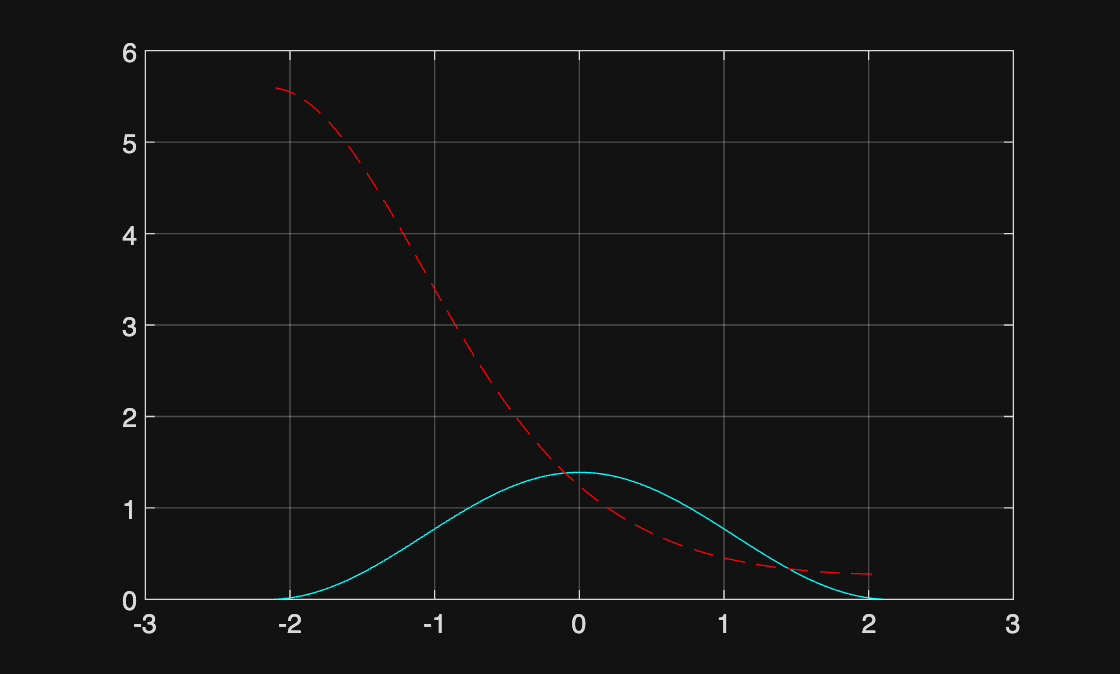

%plot(z, CrHeatFlux)
figure(11); grid on; box on; hold on;
plot(z, HotChannelHeatFlux ./ 1e6, '-c')
plot(z, CrHeatFlux ./ 1e6, '--r')
hold off;

DNBR:

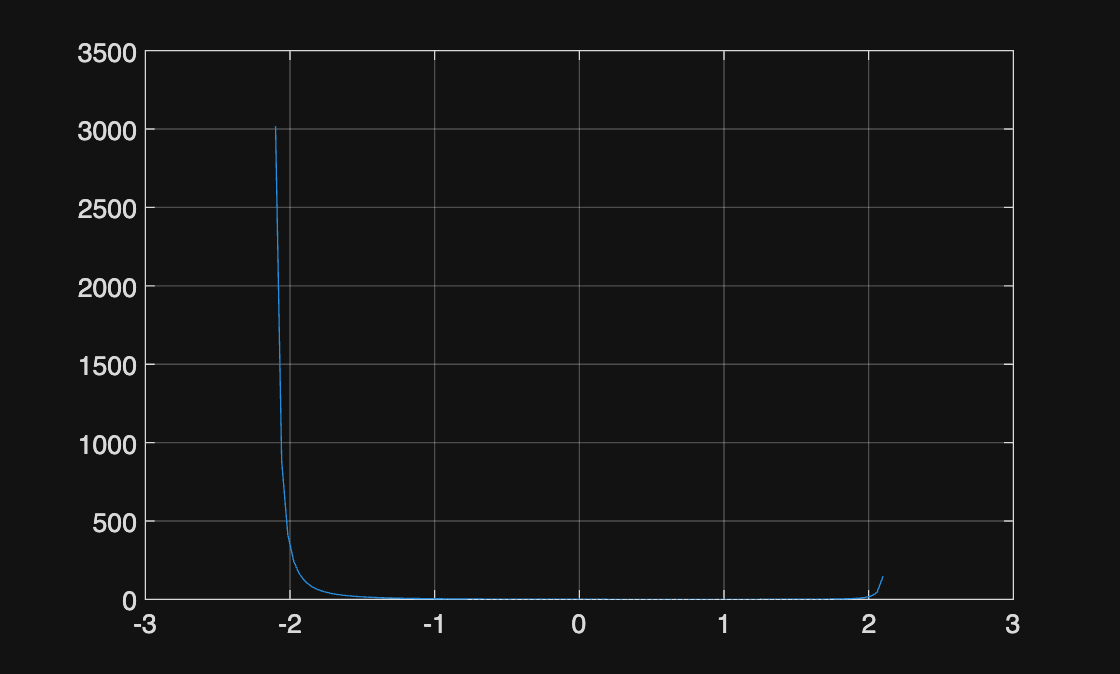

DNBR = CrHeatFlux ./ HotChannelHeatFlux;
plot(z, DNBR)
grid on; box on;

MDNBR = min(DNBR)

MDNBR = 0.5592